clear all
close all
clc


## Ultrasound parameters



Fs = 15.00E6;                          % sampling frequency
TxFreq = 4;                            % MHz, Transmission frequency
depth = 160.2; %placenta               % mm 
SoS = 1540;                            % m/s
g=1;


## Read rf data

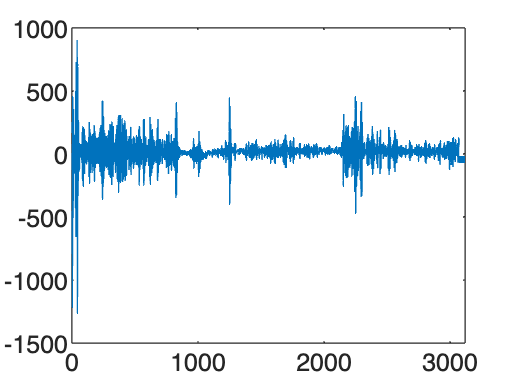


% replace with your directory
filenameRF = '/MATLAB Drive/DSPFinalProject/Codes/Posterior_Placenta/raw_1/2024-04-19t21-56-53+0000_rf.raw';
numFrames = 1;
[dataRF_sample, headerSample] = rdataread(filenameRF, numFrames);
RF = permute(dataRF_sample,[2,3,1]);
envelope = abs(hilbert(RF));
Bmode = 20.*log10(envelope);

% diplay RF data
figure, plot(RF(:,100))

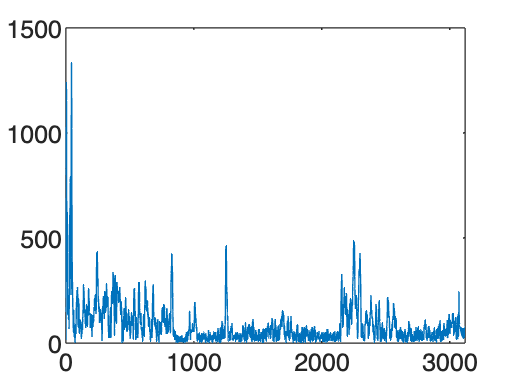

% diplay envelope data
figure, plot(envelope(:,100))

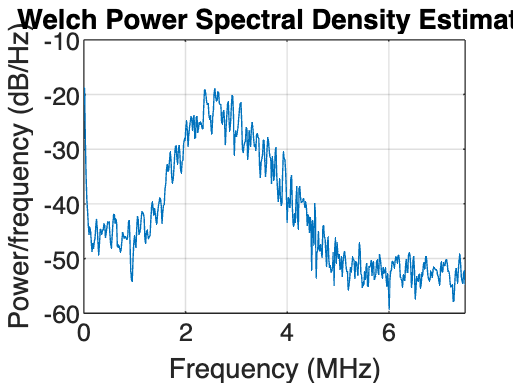


% Find the Fs1, Fs2, Fp1 and Fp2 from the following plot
figure, pwelch(RF(:,100),[],[],[],Fs)

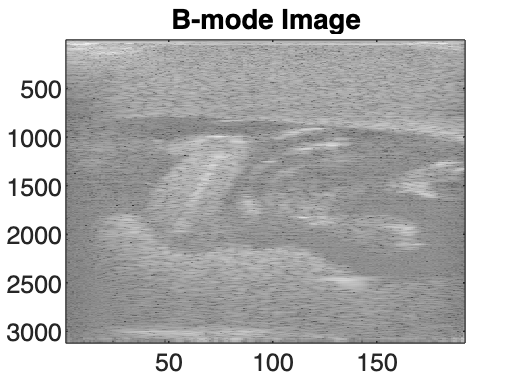

% display Bmode image
figure; 
colormap(gray)
imagesc(Bmode); title('B-mode Image')


y = filtfilt(SoS, g, RF);
envelopeFilt = abs(hilbert(y));
BmodeFilt = 20.*log10(envelopeFilt);
figure; 
colormap(gray)
imagesc(BmodeFilt); title('B-mode Image')

## Power spectral analysis

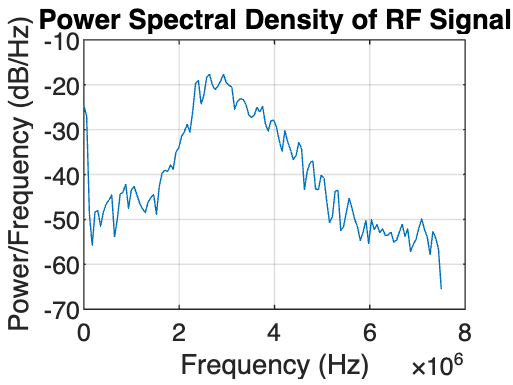


% Reduce data size for quicker PSD estimation
signal = RF(1:1000, 100);  % Take the first 1000 samples for faster computation

% Compute the Power Spectral Density (PSD) using pwelch
[Pxx, f] = pwelch(signal, [], [], [], Fs);

% Convert the PSD to dB scale
Pxx_dB = 10 * log10(Pxx);

% Plot the PSD
figure;
plot(f, Pxx_dB);
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of RF Signal');
grid on;

## Applying Filters

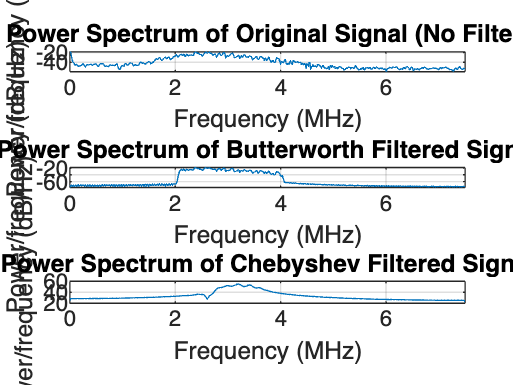

load('filter_values.mat', 'SOS_Butterworth', 'G_Butterworth', 'SOS_Chebychev', 'G_Chebychev');

% Ensure the signal is long enough for the filter
signal = RF(1:3120, 100);  % Select a portion with sufficient length for filtering

% Apply the Butterworth filter
y_butter = filtfilt(SOS_Butterworth, G_Butterworth, signal);  % Apply the Butterworth filter

% Apply the Chebyshev filter
y_cheby = filtfilt(SOS_Chebychev, G_Chebychev, signal);  % Apply the Chebyshev filter

% Plot the Power Spectrum of the Original and Filtered Signals
figure;
subplot(3, 1, 1);
pwelch(signal, [], [], [], Fs);  % Power Spectrum of the original signal (no filter)
title('Power Spectrum of Original Signal (No Filter)');

subplot(3, 1, 2);
pwelch(y_butter, [], [], [], Fs);  % Power Spectrum of Butterworth filtered signal
title('Power Spectrum of Butterworth Filtered Signal');

subplot(3, 1, 3);
pwelch(y_cheby, [], [], [], Fs);  % Power Spectrum of Chebyshev filtered signal
title('Power Spectrum of Chebyshev Filtered Signal');

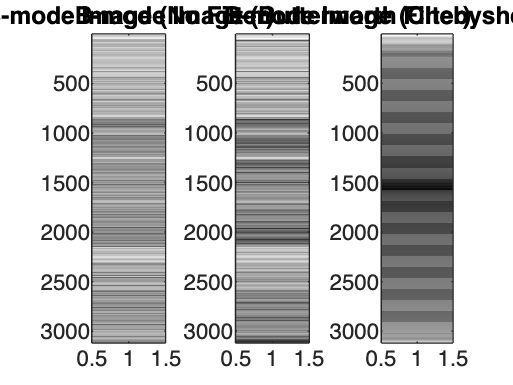


% Original B-mode image (no filter)
envelope_no_filter = abs(hilbert(signal));  % Envelope of the original signal
Bmode_no_filter = 20 .* log10(envelope_no_filter);  % B-mode image for the original signal

% B-mode image for Butterworth filtered signal
envelope_butter = abs(hilbert(y_butter));  % Envelope of the filtered signal
Bmode_butter = 20 .* log10(envelope_butter);  % B-mode image for Butterworth filtered signal

% B-mode image for Chebyshev filtered signal
envelope_cheby = abs(hilbert(y_cheby));  % Envelope of the filtered signal
Bmode_cheby = 20 .* log10(envelope_cheby);  % B-mode image for Chebyshev filtered signal

% Plot B-mode images
figure;
subplot(1, 3, 1);
colormap(gray);
imagesc(Bmode_no_filter);
title('B-mode Image (No Filter)');

subplot(1, 3, 2);
colormap(gray);
imagesc(Bmode_butter);
title('B-mode Image (Butterworth Filter)');

subplot(1, 3, 3);
colormap(gray);
imagesc(Bmode_cheby);
title('B-mode Image (Chebyshev Filter)');

## SSI Calculations

### Select Two Regions Using `imrect`

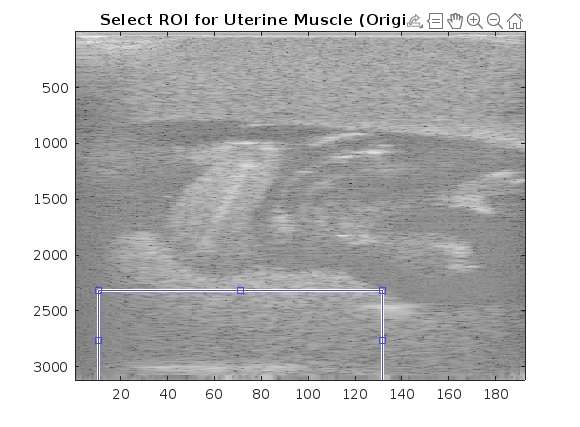

figure;
colormap(gray);
imagesc(Bmode);  % Display the B-mode image to select ROI
title('Select ROI for Uterine Muscle (Original Image)');
h = imrect;
position = wait(h);  % Wait for the user to select the region

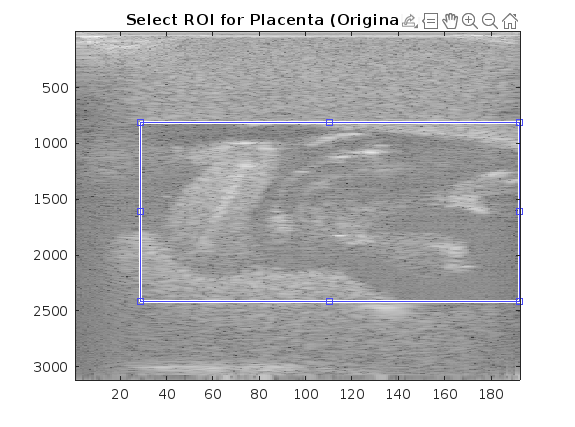

I_no_filter = imcrop(Bmode, position);  % Crop the selected region using position

% Repeat for Placenta region selection
figure;
colormap(gray);
imagesc(Bmode);  % Display the B-mode image to select ROI for Placenta
title('Select ROI for Placenta (Original Image)');
h = imrect;
position = wait(h);  % Wait for the user to select the region

I_no_filter_placenta = imcrop(Bmode, position);  % Crop the selected region using position


### Apply the Butterworth and Chebyshev Filters to the Original Signal (ROI)


% Apply the Butterworth filter to the Uterine Muscle ROI
I_butter = filtfilt(SOS_Butterworth, G_Butterworth, I_no_filter(:));

% Apply the Chebyshev filter to the Uterine Muscle ROI
I_cheby = filtfilt(SOS_Chebychev, G_Chebychev, I_no_filter(:));

% Apply the Butterworth filter to the Placenta ROI
I_butter_placenta = filtfilt(SOS_Butterworth, G_Butterworth, I_no_filter_placenta(:));

% Apply the Chebyshev filter to the Placenta ROI
I_cheby_placenta = filtfilt(SOS_Chebychev, G_Chebychev, I_no_filter_placenta(:));


### Reshape the filtered data back to the size of the ROI (Uterine Muscle and Placenta)


I_butter = reshape(I_butter, size(I_no_filter));
I_cheby = reshape(I_cheby, size(I_no_filter));

I_butter_placenta = reshape(I_butter_placenta, size(I_no_filter_placenta));
I_cheby_placenta = reshape(I_cheby_placenta, size(I_no_filter_placenta));


### Compute Variance and Mean for the Selected Regions (for both Uterine Muscle and Placenta)

format long;

% Uterine Muscle - Original (No filter)
Var_no_filter = var(I_no_filter(:));  % Variance for uterine muscle region in original image
Mean_no_filter = mean(I_no_filter(:));  % Mean for uterine muscle region in original image

% Uterine Muscle - Butterworth Filtered
Var_butter = var(I_butter(:));  % Variance for uterine muscle region in Butterworth filtered image
Mean_butter = mean(I_butter(:));  % Mean for uterine muscle region in Butterworth filtered image

% Uterine Muscle - Chebyshev Filtered
Var_cheby = var(I_cheby(:));  % Variance for uterine muscle region in Chebyshev filtered image
Mean_cheby = mean(I_cheby(:));  % Mean for uterine muscle region in Chebyshev filtered image

% Placenta - Original (No filter)
Var_no_filter_placenta = var(I_no_filter_placenta(:));  % Variance for placenta region in original image
Mean_no_filter_placenta = mean(I_no_filter_placenta(:));  % Mean for placenta region in original image

% Placenta - Butterworth Filtered
Var_butter_placenta = var(I_butter_placenta(:));  % Variance for placenta region in Butterworth filtered image
Mean_butter_placenta = mean(I_butter_placenta(:));  % Mean for placenta region in Butterworth filtered image

% Placenta - Chebyshev Filtered
Var_cheby_placenta = var(I_cheby_placenta(:));  % Variance for placenta region in Chebyshev filtered image
Mean_cheby_placenta = mean(I_cheby_placenta(:));  % Mean for placenta region in Chebyshev filtered image


### Calculate SSI for Each Region (Uterine Muscle and Placenta)


% Uterine Muscle - Original (No filter)
SSI_no_filter = sqrt(Var_no_filter / Mean_no_filter) / sqrt(var(I_no_filter(:)) / mean(I_no_filter(:)));

% Uterine Muscle - Butterworth Filtered
SSI_butter = sqrt(Var_butter / Mean_butter) / sqrt(var(I_butter(:)) / mean(I_butter(:)));

% Uterine Muscle - Chebyshev Filtered
SSI_cheby = sqrt(Var_cheby / Mean_cheby) / sqrt(var(I_cheby(:)) / mean(I_cheby(:)));

% Placenta - Original (No filter)
SSI_no_filter_placenta = sqrt(Var_no_filter_placenta / Mean_no_filter_placenta) / sqrt(var(I_no_filter_placenta(:)) / mean(I_no_filter_placenta(:)));

% Placenta - Butterworth Filtered
SSI_butter_placenta = sqrt(Var_butter_placenta / Mean_butter_placenta) / sqrt(var(I_butter_placenta(:)) / mean(I_butter_placenta(:)));

% Placenta - Chebyshev Filtered
SSI_cheby_placenta = sqrt(Var_cheby_placenta / Mean_cheby_placenta) / sqrt(var(I_cheby_placenta(:)) / mean(I_cheby_placenta(:)));

%% Display the Results for Both Uterine Muscle and Placenta
disp(['SSI for Uterine Muscle (No Filter): ', num2str(SSI_no_filter)]);

SSI for Uterine Muscle (No Filter): 1


disp(['SSI for Uterine Muscle (Butterworth Filter): ', num2str(SSI_butter)]);

SSI for Uterine Muscle (Butterworth Filter): 1


disp(['SSI for Uterine Muscle (Chebyshev Filter): ', num2str(SSI_cheby)]);

SSI for Uterine Muscle (Chebyshev Filter): 1


disp(['SSI for Placenta (No Filter): ', num2str(SSI_no_filter_placenta)]);

SSI for Placenta (No Filter): 1


disp(['SSI for Placenta (Butterworth Filter): ', num2str(SSI_butter_placenta)]);

SSI for Placenta (Butterworth Filter): 1


disp(['SSI for Placenta (Chebyshev Filter): ', num2str(SSI_cheby_placenta)]);

SSI for Placenta (Chebyshev Filter): 1


### Note

I keep getting 1 for my SSIs even though I've tried multiple different parameters for the filters.

I have absolutely no clue what I'm doing wrong. As far as I can tell, my filters are changing nothing.

This conflicts with my B-mode plots though so I have to be doing something wrong.